# Maximos y minimos

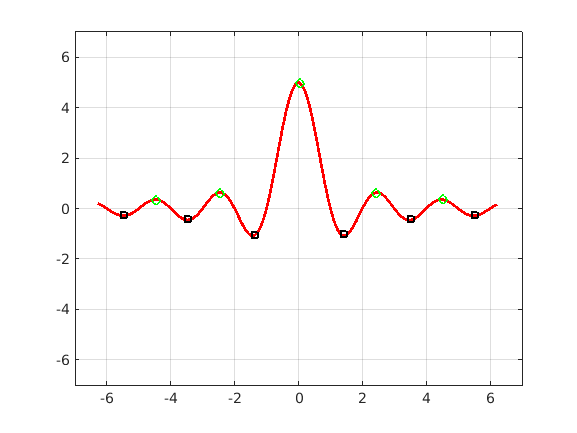

clc; clear; 

axis([-7,7,-7,7]);grid;

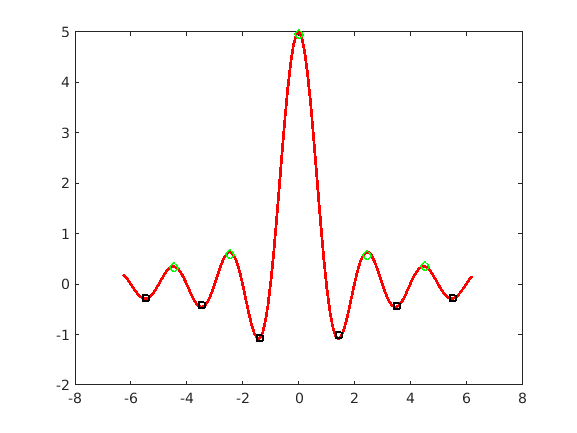

dx = 0.1;
x = -2*pi:dx:2*pi;
y1 = 5*sinc(x);
plot(x,y1,'r',"LineWidth",2); %grafica inicial
hold on; 

% ___________valor maximo absoluto______ 
% [mx1,ind] = max(y1);
% plot(x(ind),mx1,'ks',"LineWidth",2, 'MarkerSize',6);
%_______________________________________

dy = diff(y1); %funcion derivada, solo determina dy
deri = dy/dx;
% plot(x(1:end-1),deri,'b',"LineWidth",2);
s1 = sign(deri); %funcion signo (1,-1)
% plot(x(1:end-1),s1,'g',"LineWidth",2);
ders1 = diff(s1);
%plot(x(1:end-2),ders1,'b',"LineWidth",2);

%_______________minimos locales__________________

val2 = find(ders1==2); %minimo si es igual a 2
plot(x(val2+1),y1(val2),'ks',"LineWidth",2, 'MarkerSize',6);

%______________maximos locales__________________

val3 = find(ders1==-2); %maximo si es igual a -2
plot(x(val3+1),y1(val3),'go',"LineWidth",2, 'MarkerSize',6);
hold off